# Laboratorio 1: programar de manera sencilla un método numérico

## Presa - Depredador

Tomaremos el modelo presa depredador:


$$\dot{P}(t)= \alpha P(t) - \beta P(t)D(t)\\
\dot{D}(t)= \delta P(t) D(t) - \gamma D(t)$$


**Con los siguientes parámetros y estados:**

$P(t)$: Número de presas en el tiempo

$D(t)$: Depredadores en el tiempo

$\alpha$: Tasa instantánea de aumento de presas en ausencia de depredadores

$\beta$: Tasa de cacería de número de presas por depredador

$\delta$: Tasa de aumento de depredadores por presa cazada

$\gamma$: Tasa instantánea de disminución de depredadores en ausencia de presas

Programaremos de manera sencilla el método de Euler para resolver el sistema de ecuaciones diferenciales

addpath("funciones")
clear; clc; close all

**1.** Definimos el tiempo inicial y final para la simulación, junto al tamaño del paso.

t0 = 0;                         %tiempo inicial
tf = 15;                        %tiempo final
h = 0.1;                      %tamano del paso

**2.** A partir del tiempo y paso definido, creamos el vector del tiempo que usaremos para el método de Euler

DataSize = (tf - t0)/h;         %tamano de los vectores de tiempo y soluciones
t = linspace(t0, tf, DataSize); %tiempo

**3. **Tras definir el vector de tiempo, podemos crear un par de vectores que nos ayuden a guardar los valores de los estados al amplicar el método de Euler

P = zeros(DataSize, 1);
D = zeros(DataSize, 1);

**4. **Establecemos las condiciones iniciales del sistema

P(1) = 3;                   %condiciones iniciales presas
D(1) = 3;                   %condiciones iniciales depredadores

**5.** Definimos los parámetros propios del modelo presa-depredador

alpha = 1;
beta = 1;
delta = 1;
gamma = 1;

**6.** En un ciclo (de extensión igual al tiempo inicial y final predefinidos) se evaluará paso por paso el método de Euler, utilizando el modelo de presa depredador y la siguiente estructura matemática:


$$t_{n + 1} = t_n + h$$



$$y_{n+1} = y_n + hf(t_n, y_n)$$


%Metodo de euler directo con ecuaciones del modelo
for i = 1 : DataSize - 1
    P(i + 1) = P(i) + h * (alpha * P(i) - beta * P(i) * D(i));
    D(i + 1) = D(i) + h * (delta * P(i) * D(i) - gamma * D(i));
end

**7. **Procedemos a graficar el resultado del método de Euler

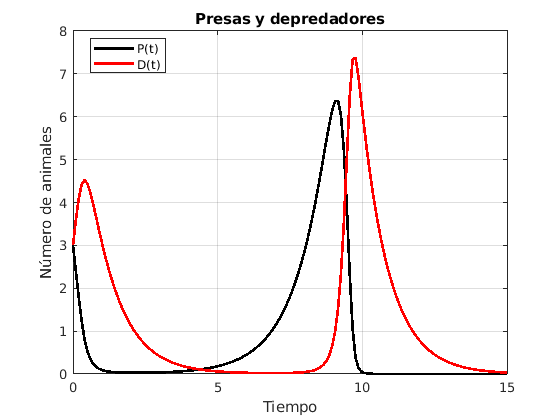

close all
figure

plot(t, P, 'k', 'linewidth', 2)
hold on
plot(t, D, 'r', 'linewidth', 2)

legend('P(t)', 'D(t)', 'Location', 'best')
xlabel('Tiempo')
ylabel('Número de animales')
title('Presas y depredadores')

grid on

**8.  **Para identificar el desempeño del método de Euler, podemos compararlo con un método numérico implementado en Matlab (*ode45*), el cual es de paso variable. Para ello, debemos de construir una función propia en Matlab. Ésta deberá contener nuestro modelo de presa-depredador (ver archivo *PresaDepredador.m*)

CondInt = [3, 3]; %Condiciones iniciales
[t_ode, N_ode] = ode45('PresaDepredador', [t0 tf], CondInt);

**9.  **Posteriormente, se grafican los resultados de ambos métodos numéricos para ambos estados.

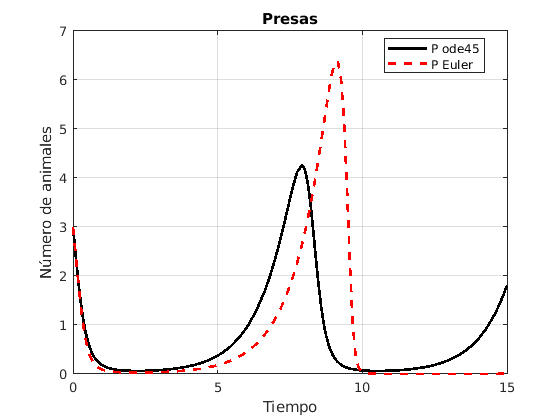

figure

plot(t_ode, N_ode(:, 1), 'k', 'linewidth', 2)
hold on
grid on
plot(t, P,'r--', 'linewidth', 2)
title('Presas')

xlabel('Tiempo')
ylabel('Número de animales')
legend('P ode45', 'P Euler', 'Location', 'best')

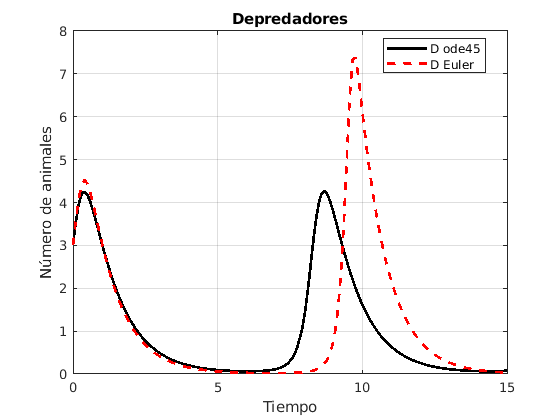


figure
plot(t_ode, N_ode(:, 2), 'k', 'linewidth', 2)
hold on
grid on
plot(t, D,'r--', 'linewidth', 2)
legend('D ode45', 'D Euler', 'Location', 'best')
title('Depredadores')

xlabel('Tiempo')
ylabel('Número de animales')

## **Otro ejemplo: Modelo SIR clásico**

El siguiente modelo epidemiológico corresponder a la dinámica de transmisión de una enfermedad infecciosa


$$\dot{S}(t) = - \frac{\beta I(t) S(t)}{N}\\
\dot{I}(t) = \frac{\beta I(t) S(t)}{N} -\gamma I(t) \\
\dot{R}(t) =\gamma I(t) $$


De manera similar al código presentado en la sección de presa-depredador, se puede escribir un código para resolver este sistema de ecuaciones a través del método de Euler:

**1. **Definir tiempo inicial, final y tamaño de paso.

clear all; close all; clc
t0 = 0;                   %tiempo inicial
tf = 150;                 %tiempo final
h = 0.001;                %tamano del paso
DataSize = (tf - t0)/h;   %tamano del vector de soluciones
t = linspace(t0, tf, DataSize);

**2. **Iniciarlizar los vectores de los estados con sus respectivas condiciones iniciales

S = zeros(DataSize, 1);
I = zeros(DataSize, 1);
R = zeros(DataSize, 1);

S(1) = 250;               %condiciones iniciales susceptibles
I(1) = 1;                  %condiciones iniciales infectados
R(1) = 0;                  %conbdiciones iniciales recuperdos
N = S(1) + I(1) + R(1);    %Poblacion total 

**3.** Definición de los parámetros del modelo

%parámetros del modelo
beta = 0.3;
gamma = 0.1;

**4.** Implementació del método de Euler con las ecuaciones del modelo


$$t_{n + 1} = t_n + h$$



$$y_{n+1} = y_n + hf(t_n, y_n)$$


for i = 1 : DataSize - 1  
    S(i + 1) = S(i) + h * (-beta * I(i) * S(i)/N);
    I(i + 1) = I(i) + h * (beta * I(i) * S(i)/N - gamma * I(i)); 
    R(i + 1) = R(i) + h * (gamma * I(i));
end

**5.** Graficar el resultado del método numérico

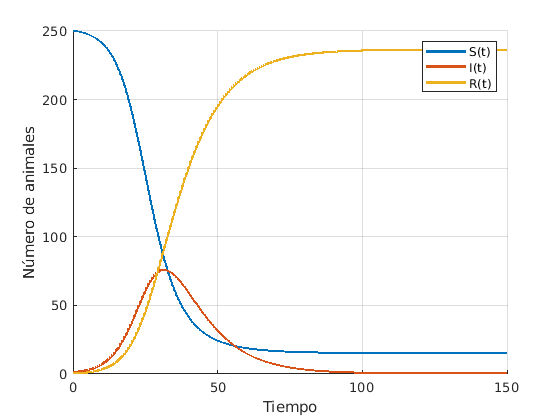

close all

figure
hold on
plot(t, S, 'linewidth', 2)
plot(t, I, 'linewidth', 2)
plot(t, R, 'linewidth', 2)

legend('S(t)','I(t)','R(t)')
xlabel('Tiempo')
ylabel('Número de animales')

grid on

# Opcional: Métodos numéricos creando y usando funciones creadas por el usuario 

En esta sección se muestra como "optimizar" lineas de código a través de crear funciones que se puedaen utilizar en múltiple situaciones.

1. Similar a los anteriores casos, se definen el tiempo inicial, final y el tamaño del paso.

close all; clear all; clc
t0 = 0;
tf = 10;
h = 0.01;
CondInt = [3 3]; %matriz de condiciones iniciales
te = linspace(t0, tf, (tf - t0)/h);

Podemos realizar el método de Euler utilizando la función *MetEuler*, ingresando cada uno de los parámetros que dicha función requiere: 

    - Modelo matemático definido en un archivo *.m *(en este caso *PresaDepredador*)

    - Condiciones iniciales

    - Tiempo final

    - Tamaño del paso

%metodo de euler
Ne = MetEuler(@PresaDepredador, CondInt, tf, h);

Al correr dicha función, los resultados se guardan en una matriz, donde la primera fila son las presas y la segunda son los depredadores

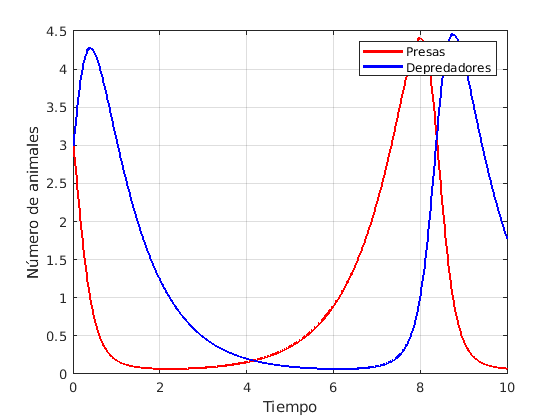

plot(te, Ne(1, :), 'r', 'LineWidth',2);
hold on
plot(te, Ne(2, :), 'b', 'LineWidth',2);

legend('Presas', 'Depredadores')
ylabel('Número de animales');
xlabel('Tiempo');
grid on